# Pole Placement

JJRATH- Feb2021 State Feedback Design Based on Pole Placement

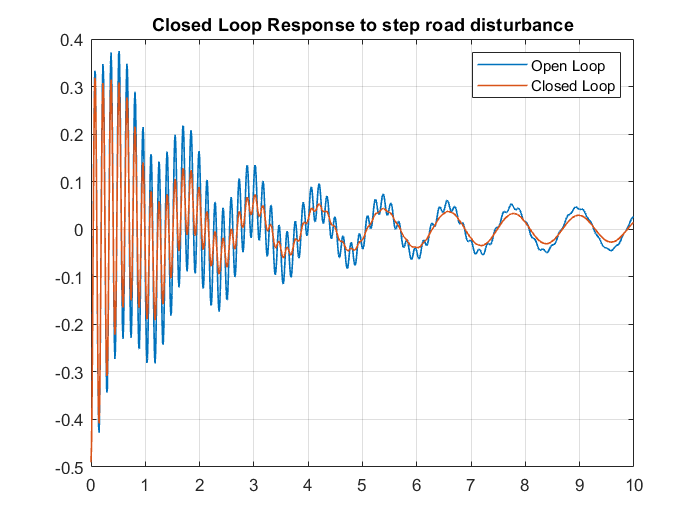

%--------------------------
%----------------------------
% Ex1: Active Suspension System
% qcar_CT = SISO_Nom_Suspension; % The nominal suspension model
qcar_CT = SISO_Dis_suspension; % The disturbed suspension model
t = 0:.01:10-0.01;
%-- Design Requirements
% A suspension system should have satisfactory road holding ability, 
% while still providing comfort when riding over bumps and holes in the road.
% When the vehicle is experiencing any road disturbance (i.e. pot holes, cracks, and uneven pavement),
% the vehicle body should not have large oscillations, and the oscillations 
% should dissipate quickly. Let us consider the suspension deflection as the output for this probelm.
% The road disturbance (W) in this problem will be simulated by a step input.
% This step could represent the vehicle coming out of a pothole. 
% We want to design a controller so that the output (xb-xw) has an overshoot less than 5
% and a settling time shorter than 5 seconds.
% For example, when the bus runs onto a 10-cm step, the bus body will oscillate within a range of +/- 5 mm and
% return to a smooth ride within 5 seconds.

%---- STEP 1: Getting the TF of the inputs w.r.t output
[NUM1,DEN1] = ss2tf(qcar_CT.a,qcar_CT.b,qcar_CT.c,qcar_CT.d,1); % TF respect to input 1 i.e. fs
[NUM2,DEN2] = ss2tf(qcar_CT.a,qcar_CT.b,qcar_CT.c,qcar_CT.d,2); % TF respect to input 2 i.e. ft
H1_11 = tf(NUM1,DEN1); % TF of output 1 and input 1
H1_12 = tf(NUM2,DEN2); % TF of output 1 and input 2

%-- STEP 2: Check Open Loop Poles 
P_ol = eig(qcar_CT);
[wn,zeta] = damp(H1_11); 

%-- STEP 3: Use Pole placement to move the close loop pole
%-- Lets change the real part the closed loop poles to reduce the oscillations
P_des = [-.1+5.2457i,-.1-5.2457i,-1+42.6209i,-1-42.6209i ]; % For example


K_pl = place(qcar_CT.a,qcar_CT.b(:,1),P_des); % Determines the gain K for the A, B and desired poles
K_ac = acker(qcar_CT.a,qcar_CT.b(:,1),P_des); % Determines the gain K for the A, B and desired poles

%-- STEP 4: Express the closed loop dynamics
A_cl = qcar_CT.a-qcar_CT.b(:,1)*K_pl;
B_cl = qcar_CT.b(:,2) ; % The road disturbance
C_cl = qcar_CT.c;
D_cl = qcar_CT.d(:,2);
Cl_qcar_CT = ss(A_cl,B_cl,C_cl,D_cl); % The closed loop plant dynamics
P_cl = eig(Cl_qcar_CT); % The closed loop system poles
[wncl,zeta_cl] = damp(Cl_qcar_CT);


%--- STEP 5: Compare response to a unit step disturbance
%--- System response of SS considering road disturbance, 
u_road = 0.1*ones(1,length(t)); % % Random road disturbance i.e. a step of magnitude 0.1
x0_f = [0.01 0.1 0.5 .1]; % Initial conditions are  non- zero.
%--- Simulate 
[Yol_d,t,Xol_d] = lsim(qcar_CT,[u_road*0; u_road],t,x0_f); % Disturbed open loop plant


[Ycl_d,t,Xcl_d] = lsim(Cl_qcar_CT,[u_road],t,x0_f); % Disturbed closed loop plant 
%-- Plot the response
figure; 
plot(t,Yol_d,'LineWidth',1); grid on; hold on;
plot(t,Ycl_d,'LineWidth',1);
legend('Open Loop','Closed Loop')
title('Closed Loop Response to step road disturbance')